# Лабораторная работа №1

## Гистограммы, профили и проекции

**Гистограмма изображения**

clc
clear all

I = imread("evening.jpg");
[numRows, numCols, Layers] = size(I);

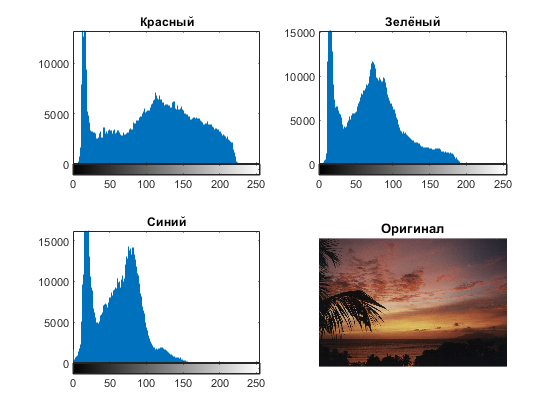

figure;

subplot(2,2,1)
imhist(I(:, :, 1))
title('Красный')

subplot(2,2,2)
imhist(I(:, :, 2))
title('Зелёный')

subplot(2,2,3)
imhist(I(:, :, 3))
title('Синий')

subplot(2,2,4)
imshow(I)
title('Оригинал')

**Арифметические преобразования**

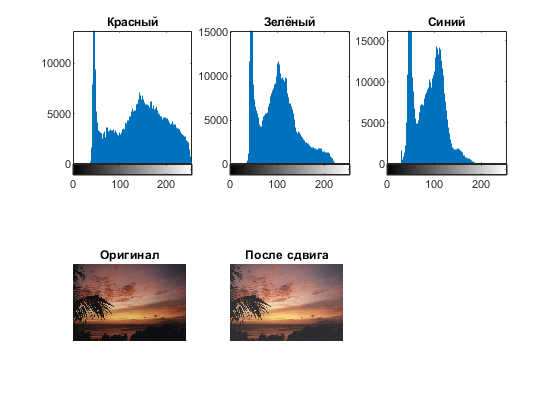

for i = 1:1:Layers
    for j = 1:1:numRows
        for k = 1:1:numCols
            Inew(j,k,i) = I(j,k,i) + 30;
        end
    end
end

figure;

subplot(2,3,1)
imhist(Inew(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')


subplot(2,3,5)
imshow(Inew)
title('После сдвига')

**Нелинейное растяжение динамического диапазона**

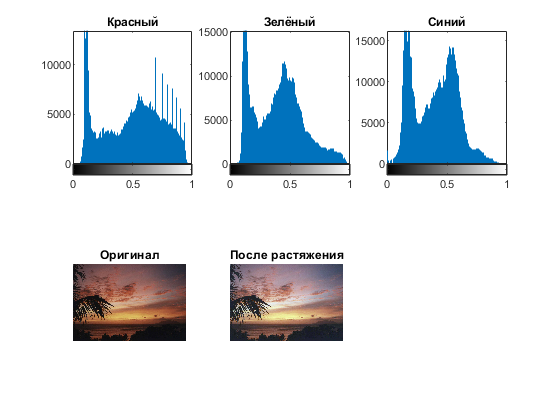

alpha = 0.8;
for k = 1:1:Layers
    Imin = min(min(I(:,:,k)));
    Imax = max(max(I(:,:,k)));
    for i = 1:1:numRows
        for j = 1:1:numCols
            Inew_din(i,j,k) = ((double(I(i,j,k) - Imin) / double(Imax - Imin))) ^ alpha;
        end
    end
end

figure;

subplot(2,3,1)
imhist(Inew_din(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_din(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_din(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')


subplot(2,3,5)
imshow(Inew_din)
title('После растяжения')

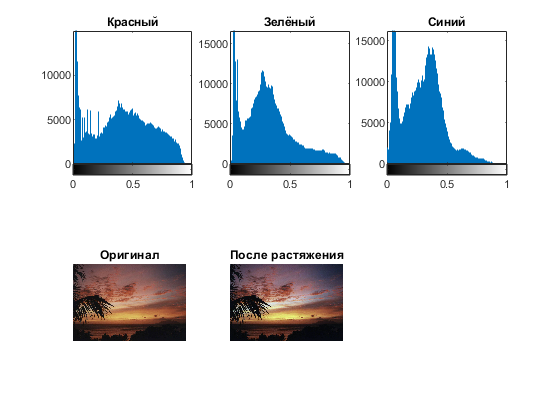

alpha = 1.3;
for k = 1:1:Layers
    Imin = min(min(I(:,:,k)));
    Imax = max(max(I(:,:,k)));
    for i = 1:1:numRows
        for j = 1:1:numCols
            Inew_din(i,j,k) = ((double(I(i,j,k) - Imin) / double(Imax - Imin))) ^ alpha;
        end
    end
end

figure;

subplot(2,3,1)
imhist(Inew_din(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_din(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_din(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')


subplot(2,3,5)
imshow(Inew_din)
title('После растяжения')

**Равномерное преобразование**

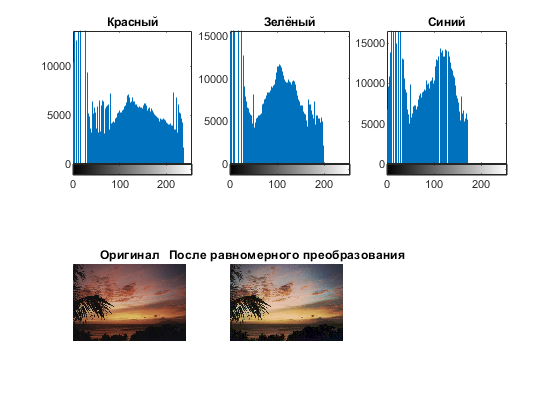

for k = 1:1:Layers
    H = imhist(I(:,:,k));
    CH = cumsum(H) / (numCols * numRows);
    Imin = min(min(I(:,:,k)));
    Imax = max(max(I(:,:,k)));
    for i = 1:1:numRows
        for j = 1:1:numCols
            ind = I(i,j,k);
            if ind == 0  % чтобы не ругался на ошибку
                ind = 1; % "индексы должны быть целыми положительными"
            end
            Inew_uni(i,j,k) = double(Imax-Imin) * CH(ind) + Imin/255;
        end
    end
end

figure;

subplot(2,3,1)
imhist(Inew_uni(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_uni(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_uni(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_uni)
title('После равномерного преобразования')

**Экспоненциальное преобразование**

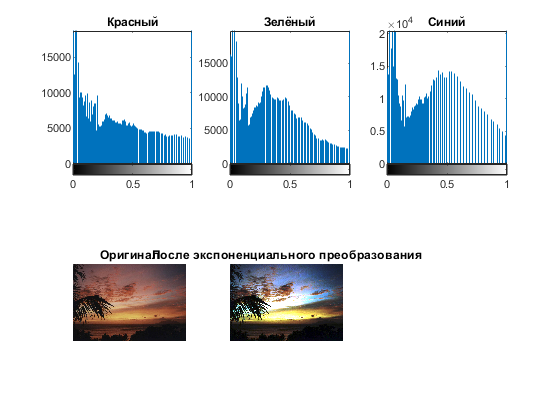

alpha = 2.5;
for k = 1:1:Layers
    H = imhist(I(:,:,k));
    CH = cumsum(H) / (numCols * numRows);
    Imin = min(min(I(:,:,k)));
    Imax = max(max(I(:,:,k)));
    for i = 1:1:numRows
        for j = 1:1:numCols
            ind = I(i,j,k);
            if ind == 0  % чтобы не ругался на ошибку
                ind = 1; % "индексы должны быть целыми положительными"
            end
            Inew_exp(i,j,k) = double(Imin) - 1/alpha * log(1 - CH(ind)) ;
        end
    end
end

figure;

subplot(2,3,1)
imhist(Inew_exp(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_exp(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_exp(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_exp)
title('После экспоненциального преобразования')

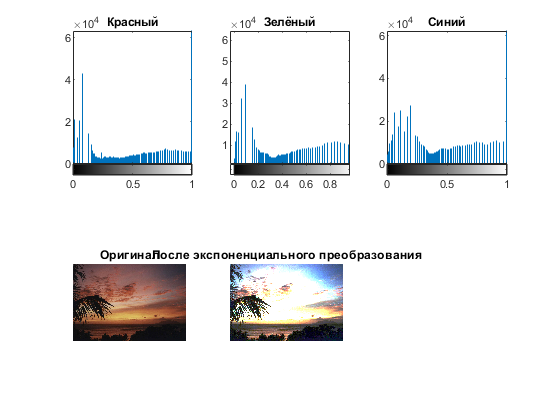

alpha = 0.9;
for k = 1:1:Layers
    H = imhist(I(:,:,k));
    CH = cumsum(H) / (numCols * numRows);
    Imin = min(min(I(:,:,k)));
    Imax = max(max(I(:,:,k)));
    for i = 1:1:numRows
        for j = 1:1:numCols
            ind = I(i,j,k);
            if ind == 0  % чтобы не ругался на ошибку
                ind = 1; % "индексы должны быть целыми положительными"
            end
            Inew_exp(i,j,k) = double(Imin) - 1/alpha * log(1 - CH(ind)) ;
        end
    end
end

figure;

subplot(2,3,1)
imhist(Inew_exp(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_exp(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_exp(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_exp)
title('После экспоненциального преобразования')

**Преобразование по закону Рэлея**

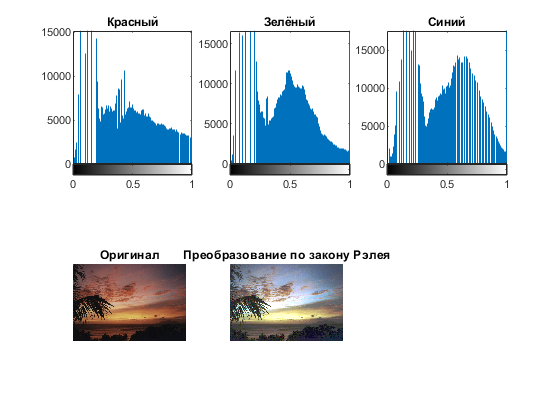

alpha = 0.4;
for k = 1:1:Layers
    H = imhist(I(:,:,k));
    CH = cumsum(H) ./ (numCols * numRows);
    Imin = min(min(I(:,:,k)));
    for i = 1:1:numRows
        for j = 1:1:numCols
            ind = I(i,j,k);
            if ind == 0  % чтобы не ругался на ошибку
                ind = 1; % "индексы должны быть целыми положительными"
            end
            Inew_rel(i,j,k) = double(Imin) + (2 * alpha^2 * log(1 / (1 - CH(ind))))^(1/2);
        end
    end
end


figure;
subplot(2,3,1)
imhist(Inew_rel(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_rel(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_rel(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_rel)
title('Преобразование по закону Рэлея')

**Преобразование по закону 2/3**

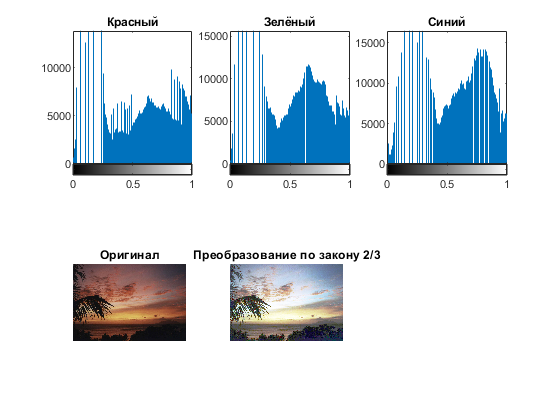


for k = 1:1:Layers
    H = imhist(I(:,:,k));
    CH = cumsum(H) ./ (numCols * numRows);
    for i = 1:1:numRows
        for j = 1:1:numCols
            ind = I(i,j,k);
            if ind == 0  % чтобы не ругался на ошибку
                ind = 1; % "индексы должны быть целыми положительными"
            end
            Inew_23(i,j,k) = CH(ind)^(2/3);
        end
    end
end

figure;
subplot(2,3,1)
imhist(Inew_23(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_23(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_23(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_23)
title('Преобразование по закону 2/3')

**Гиперболическое преобразование**

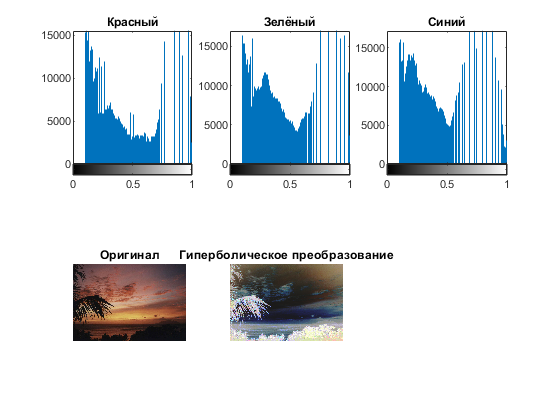

% альфа не должна равняться 0, иначе будет чёрный квадрат
alpha = 0.1;
for k = 1:1:Layers
    H = imhist(I(:,:,k));
    CH = cumsum(H) ./ (numCols * numRows);
    Imin = min(min(I(:,:,k)));
    for i = 1:1:numRows
        for j = 1:1:numCols
            ind = I(i,j,k);
            if ind == 0  % чтобы не ругался на ошибку
                ind = 1; % "индексы должны быть целыми положительными"
            end
            Inew_hip(i,j,k) = alpha^CH(ind);
        end
    end
end
figure;
subplot(2,3,1)
imhist(Inew_hip(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_hip(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_hip(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_hip)
title('Гиперболическое преобразование')

#### **Применение встроенных функций**

**Повышение контрастности с помощью imadjust**

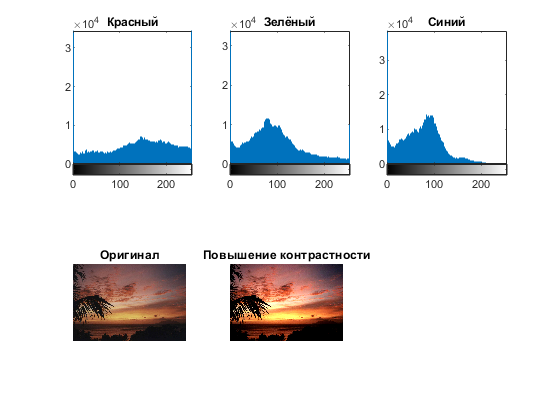

Inew_imag = imadjust(I,[0.1 0.7]);

figure;
subplot(2,3,1)
imhist(Inew_imag(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_imag(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_imag(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_imag)
title('Повышение контрастности')

**Эквализация изображения с помощью histeq()**

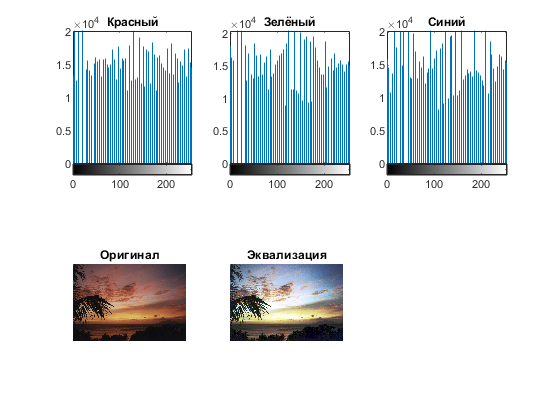

for k = 1:1:Layers;
    Inew_eq(:,:,k) = histeq(I(:,:,k));
end
figure;
subplot(2,3,1)
imhist(Inew_eq(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_eq(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_eq(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_eq)
title('Эквализация')

**Адаптивная эквализация с помощью adapthisteq()**

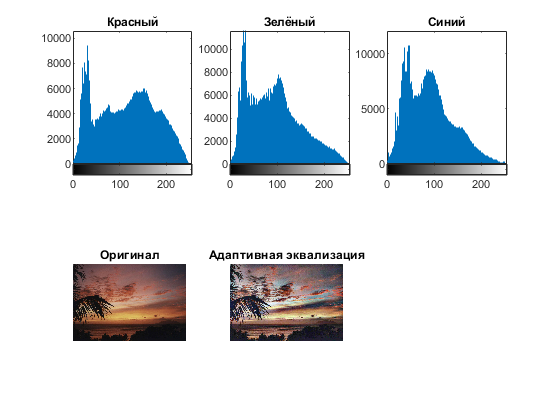

for k = 1:1:Layers;
    Inew_adeq(:,:,k) = adapthisteq(I(:,:,k));
end
figure;
subplot(2,3,1)
imhist(Inew_adeq(:, :, 1))
title('Красный')

subplot(2,3,2)
imhist(Inew_adeq(:, :, 2))
title('Зелёный')

subplot(2,3,3)
imhist(Inew_adeq(:, :, 3))
title('Синий')

subplot(2,3,4)
imshow(I)
title('Оригинал')

subplot(2,3,5)
imshow(Inew_adeq)
title('Адаптивная эквализация')

**Сравнение результатов**

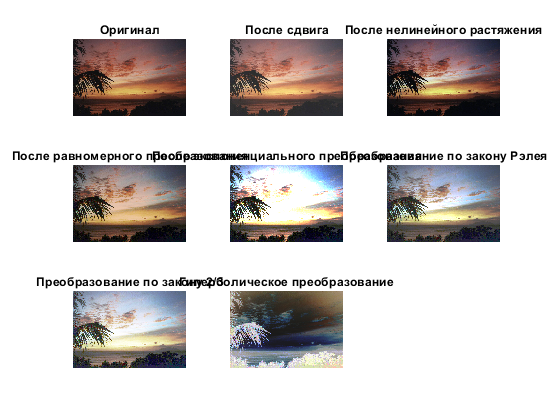

figure
subplot(3,3,1)
imshow(I)
title('Оригинал')

subplot(3,3,2)
imshow(Inew)
title('После сдвига')

subplot(3,3,3)
imshow(Inew_din)
title('После нелинейного растяжения')

subplot(3,3,4)
imshow(Inew_uni)
title('После равномерного преобразования')

subplot(3,3,5)
imshow(Inew_exp)
title('После экспоненциального преобразования')

subplot(3,3,6)
imshow(Inew_rel)
title('Преобразование по закону Рэлея')

subplot(3,3,7)
imshow(Inew_23)
title('Преобразование по закону 2/3')

subplot(3,3,8)
imshow(Inew_hip)
title('Гиперболическое преобразование')

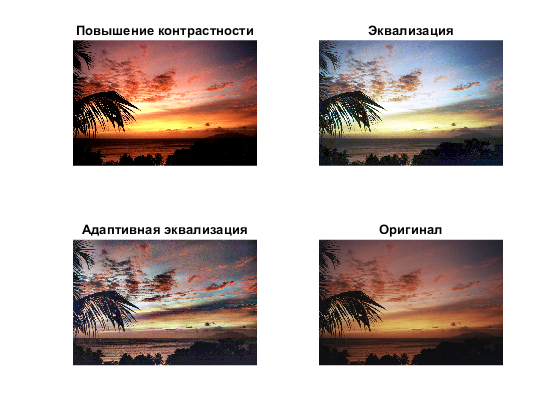


figure;
subplot(2,2,1)
imshow(Inew_imag)
title('Повышение контрастности')

subplot(2,2,2)
imshow(Inew_eq)
title('Эквализация')

subplot(2,2,3)
imshow(Inew_adeq)
title('Адаптивная эквализация')

subplot(2,2,4)
imshow(I)
title('Оригинал')

**Профиль изображения**

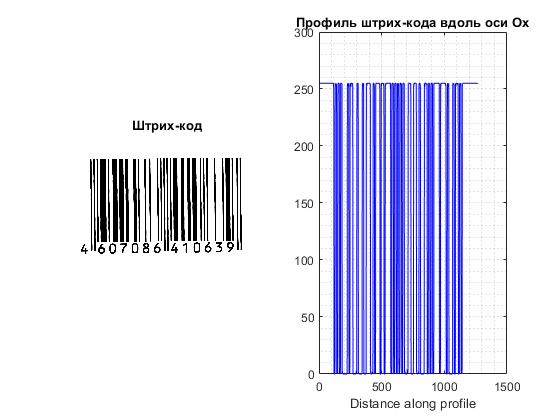

I = imread("code.jpg");
[numRows, numCols, Layers] = size(I);
x = [1 numCols];
y = [ceil(numRows/2) ceil(numRows/2)];
figure;
subplot(1,2,1)
imshow(I)
title('Штрих-код')
subplot(1,2,2)
improfile(I,x,y), grid minor;
title('Профиль штрих-кода вдоль оси Ох')

**Проекция**

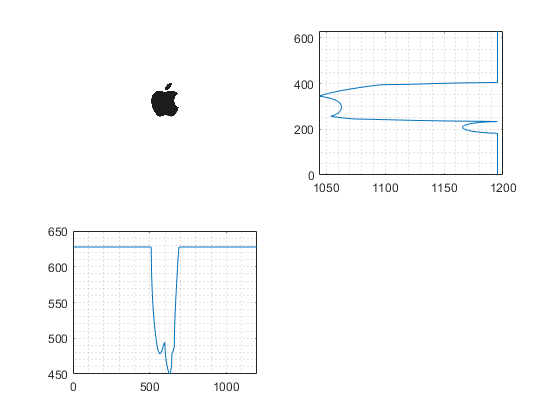

I = imread("apple.jpg");
[numRows, numCols, Layers] = size(I);
for i=1:1:numRows
    Proj_Y(i,1)= (round(sum(I(i,:,1))) +  round(sum(I(i,:,2))) + round(sum(I(i,:,3)))) / (256 * 3);
end
for i=1:1:numCols
    Proj_X(1,i)= (round(sum(I(:,i,1))) +  round(sum(I(:,i,2))) + round(sum(I(:,i,3)))) / (256 * 3);
end
figure;
subplot(2,2,1)
imshow(I)
subplot(2,2,2)
plot(Proj_Y, 1:numRows)
grid minor
subplot(2,2,3)
plot(1:numCols, Proj_X)
grid minor